# **EXTRACT**: **t**ractable and **r**obust  **a**utomated **c**ell extraction **t**ool for calcium imaging

It ***extracts*** the activities of cells as time series from both one-photon and two-photon Ca2+ imaging movies

## Introduction to the EXTRACT pipeline

Steps:

- **Input raw movie:** The pipeline takes a raw 1p/2p Ca2+ imaging movie as an  input.

- **Pre-processing:** Perform motion correction using exisiting external algorithms (for example: [NoRMCorre](https://github.com/flatironinstitute/NoRMCorre)).  and various pre-processing steps. EXTRACT has a configuration to perform the usual pre-processing steps including taking dF/F, highpass filtering for suppressing excessive background, and circular masking for endoscopic movies (see Configuration details).

- **EXTRACT: **The pre-processed movie is used by the EXTRACT algorithm to perform tractable and robust cell extraction.

- **Cell sorting:** One can use either EXTRACT's internal sorter or use an external sorter for this step.

- **Output:** The output consists of temporal traces and spatial maps for future data analysis.

- **Cell checker**: EXTRACT has an internally built-in cell-check algorithm, which employs  semi-supervised machine learning methods to aid the user with the cell  checking process (see cell checker for details).

EXTRACT code in this repository provides most of the pipeline (colored as green in the figure). We also provide some links to the external repositories whenever needed (colored as orange in the figure).

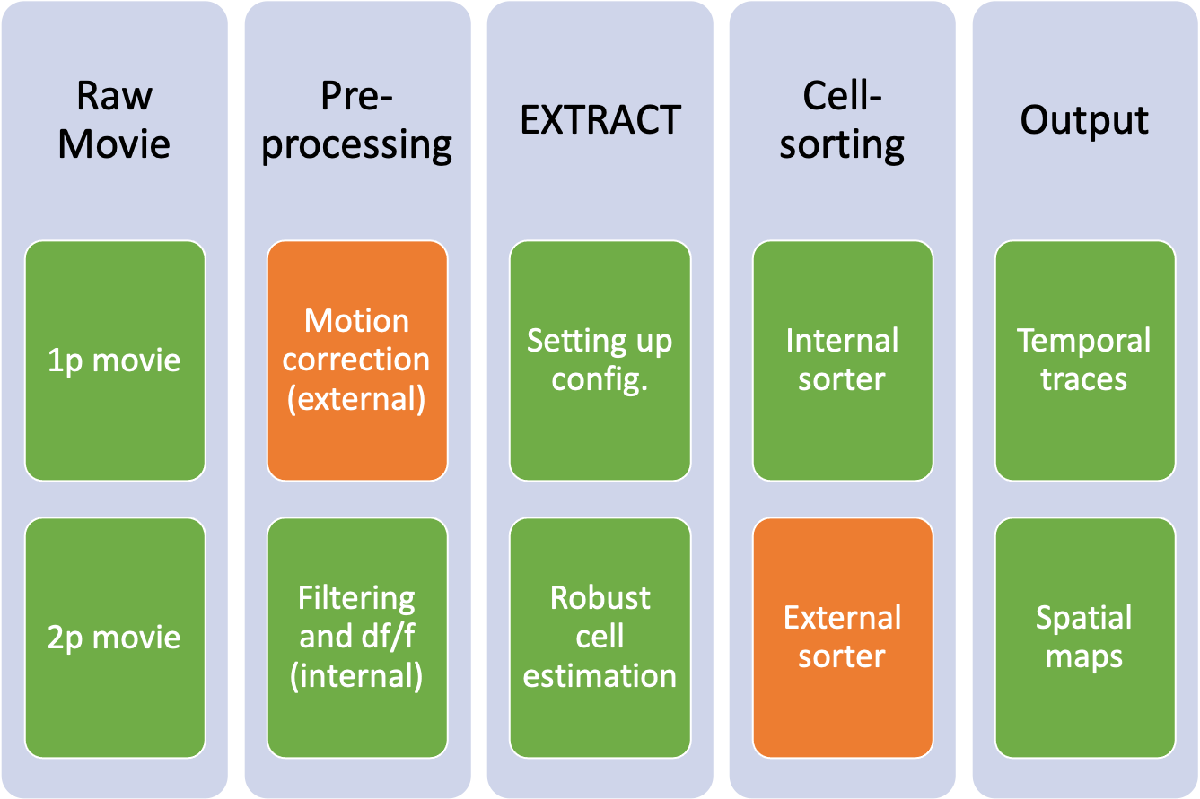

Figure credit: Schnitzer Lab

## **Dependencies**

Before running the utorial, first check that all the dependencies are installed. EXTRACT requires, at least, the following toolboxes. With future releases, there may be need for further toolboxes.

- Bioinformatics Toolbox

- Econometrics Toolbox

- Image Processing Toolbox

- Parallel Computing Toolbox

- Signal Processing Toolbox

- Statistics and Machine Learning Toolbox

- Wavelet Toolbox

## Input

It is a good practice to clear the RAM before loading the input data and performing cell extraction. In this tutorial, the input file (example.mat)

contains a movie M, ground truth spatial cell maps (S_ground), and ground truth time-series traces (T_ground).

clear;
load('example.mat'); 


## Configurations

It is essential to define the configuration to be used for running EXTRACT. To know the full list of advanced configurations and their defaults, see this: [Configurations](https://github.com/schnitzer-lab/EXTRACT-public#configurations)

### Default configurations

config = [];
config = get_defaults(config); 


### Essential configuration

It is essential to define the average cell radius, without this EXTRACT will give an error.

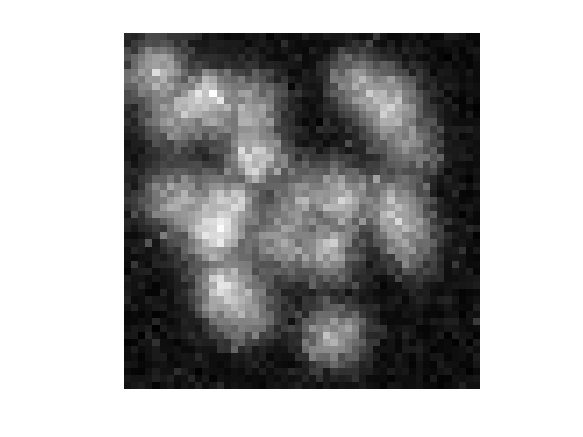


% By considering the maximum projections, pick an estimate cell radius
figure, imshow(max(M,[],3),[]);



config.avg_cell_radius = 7; % Average cell radius is 7.



### Optional configurations

While these are optional, it is strongly advised to handpick the following configurations. 

For this tutorial, the example movie is small enough that EXTRACT will not automatically partition this, but it is a good idea to keep the following in mind. Change the number of partitions for loading movies that won't fit into the RAM. 

config.num_partitions_x=1;
config.num_partitions_y=1; 

Choose the output trace option: 'nonneg' for non-negative Ca2+ traces, 'raw' for raw ones.

config.trace_output_option='raw'; 

If the movie is clean enough (as in this tutorial), there is no need to lowpass filter it. Else use of the spatial smoothing filter options for finding cells.

config.cellfind_filter_type='none';

Keeping verbose=2 gives insight into the EXTRACTion process. It is always advised to keep verbose=2.

config.verbose=2; 

no need for highpass filtering

config.spatial_highpass_cutoff=inf; 

no need for background removal

config.remove_background=0;

### Optional configurations whose defaults exist

This is a small dataset, will be fast on cpu anyways.

config.use_gpu=0; 

10 is a good number of iterations for this dataset.

config.max_iter = 10; 

Adaptive kappa is on for this movie. For an actual movie, keeping it off may be beneficial depending on the noise levels.

config.adaptive_kappa = 1;

Default snr is 1, lower this (never less than 0) to increase cell count at the expense of more spurious cells!

config.cellfind_min_snr=0.5;

### Advanced configurations

- `preprocess`: EXTRACT does preprocessing steps such as  taking dF/F, highpass filtering for suppressing excessive background,  and circular masking for endoscopic movies. Set to `false` to skip all preprocessing. Default: `true`.

- `downsample_time_by`, `downsample_space_by`: Downsampling factors. Set to `'auto'` for automatic downsampling factors based on avg cell radius and avg calcium event time constant. Defaults: `1` & `1`.

- `multi_gpu``:` Boolean flag for parralel processing of different movie partitions on multiple GPUs (if applicable) in the GPU mode. Default: `false`.

- `parallel_cpu:` Boolean flag for parallel processing of different movie partitions in the CPU mode. This flag is only effective when `use_gpu = 0`. Default: `false`.

- `num_parallel_cpu_workers``:` When `config.parallel_cpu = 1`, this parameter can be used to set the desired number of CPU workers.  Default is # of available cores to Matlab - 1 (minus 1 is for leaving  compute room for other tasks).

- `min_radius_after_downsampling`: When `downsample_space_by= 'auto'`, this determines the spatial downsampling factor by setting a minimum avg radius after downsampling. Default: `5`.

- `min_tau_after_downsampling`: When `downsample_time_by='auto'`, this determines the temporal downsampling factor by setting a minimum event tau after downsampling. Default: `5`.

- `reestimate_S_if_downsampled`: When set to `true`, images are re-estimated from full movie at the end. When `false`, images are upsampled by interpolation. `reestimate_S_if_downsampled=true` is not recommended as precise shape of cell images are typically not essential, and re-estimation from full movie is costly.

- `verbose`: Log is emitted from the console output when set to `1`, set to `0` to suppress output. When set to `2`, EXTRACT provides a detailed summary during the signal extraction process. Default: `2`.

- `crop_cicrcular`: For microendoscopic movies, set it to `true` for automatically cropping out the region outside the circular imaging region. Default: `false`.

- `dendrite_aware`: Boolean flag, set it to `true` if dendrites exist in the movie & are desired in the output. Default: `false`.

- `adaptive_kappa`: If `true`, then during cell finding, the robust esimation loss will adaptively set its robustness parameter. Default: `false`.

- `smoothing_ratio_x2y`: If the movie contains mainly  objects that are elongated in one dimension (e.g. dendrites), this  parameter is useful for more smoothing in either x or y dimension.  Default: `1`.

- `compact_output`: If set to `true`, then the  output will not include bad components that were found but then  eliminated. This usually reduces the memory used by the output struct  substantially. Default: `true`.

- `use_sparse_arrays`: If set to `true`, then the output cell images will be saved as sparse arrays. Default: `true`.

- `temporal_denoising`: Boolean flag that determines  whether to apply temporal wavelet denoising. This functionality is  experimental; expect it to increase runtime considerably if the input  movie has >10K frames and hase larger field of view than 250x250  pixels. Default: `false`.

- `remove_background`. Boolean flag that determines whether to subtract the (spatially) background (largest spatiotemporal mode of  the movie matrix). Default: `true`.

- `cellfind_max_steps`: Maximum number of cell candidate initialization during cell finding step. Default: `1000`.

- `cellfind_kappa_std_ratio`: Kappa will be set to this times the noise std for the component-wise EXTRACT during initialization. Default: `1`.

- `cellfind_filter_type`: Type of the spatial smoothing filter used for cell finding. Options: `'butter'` (IIR butterworth filter), `'gauss'` (FIR filter with a gaussian kernel), `'wiener'` (wiener filter), `'movavg'` (moving average in space), `'none'` (no filtering). Default: `'butter'`.

- `spatial_highpass_cutoff`, `spatial_lowpass_cutoff`: These cutoffs determine the strength of butterworth spatial filtering  of the movie (higher values = more lenient filtering), and are relative  to the average cell radius. Defaults: `5` & `2`.

- `init_with_gaussian`: If true, then during cell finding,  each cell is initialized with a gaussian shape prior to robust  estimation. If false, then initialization is done with a correlation  image (preferred for movies with dendrites). Default: `false`.

- `cellfind_numpix_threshold`: During cell finding, objects with an area < `cellfind_numpix_threshold` are discarded. Default: `9`.

- `S_init`: Optionally, provide cell images in `config.S_init` as a 2-D matrix (with the size of the first dimension equal to movie  height x movie width), and the algorithm will use these as the initial  set of cells, skipping its native initialization. Default: empty array.

- `smooth_T` : If set to `true`, calculated traces are smoothed using median filtering. Default : `false`.

- `smooth_S` : If set to `true`, calculated images are smoothed using a 2-D gaussian filter. Default : `true`.

- `max_iter` : Maximum number of alternating estimation iterations. Default : `6`.

- `plot_loss`: When set to `true`, empirical risk is plotted against iterations during alternating estimation. Default: `false`.

- `l1_penalty_factor`: A numeric in range `[0, 1]` which determines the strength of l1 regularization penalty to be  applied when estimating the temporal components. The penalty is applied  only to cells that overlap in space and whose temoral components are  correlated. Use larger values if spurious cells are observed in the  vicinity of high SNR cells. Default: `0`.

- `max_iter_S`,`max_iter_T` : Maximum number of iterations for `S` and `T` estimation steps. Default: `100` and `100`.

- `TOL_sub` : If the 1-step relative change in the objective within each `T` and `S` optimization is less than this, the respective optimization is terminated. Default: `1e-6`.

- `kappa_std_ratio`. Kappa will be set to this times the  noise std during the cell refinement process. Lower values introduce  more robustness at the expense of an underestimation bias in `S` and `T` (especially in the low SNR regime). Default : `1`.

- `TOL_main` : If the relative change in the main objective function between 2 consecutive alternating minimization steps is less  than this, cell extraction is terminated. Default: `1e-6`.

- `medfilt_outlier_pixels`: Flag that determines whether outlier pixels in the movie should be replaced with their neighborhood median. Default: `false`.

- `remove_duplicate_cells`: For movies processed in multiple partitions, this flag controls duplicate removal in the overlap regions. Default: `true`.

- `T_dup_corr_thresh`,`S_dup_corr_thresh` : Through alternating estimation, cells that have higher trace correlation than `T_dup_corr_thresh` and higher image correlation than `S_dup_corr_thresh` are eliminated. Defaults: `0.95` & `0.95`.

- `temporal_corrupt_thresh` , `spatial_corrupt_thresh` : Spatial & temporal corruption indices are calculated at each step of the alternating minimization routine. Images / traces that have an  index higher than these are eliminated. Defaults : `0.7` & `0.7`.

- `T_min_snr` : Cells with lower SNR value than `T_min_snr` will be eliminated. Default: `10`.

We suggest checking out `get_defaults.m` for further info on how to set these parameters.

## Perform EXTRACTion

output=extractor(M,config);

17-Dec-2021 16:25:39: Signal extraction on partition 1 (of 1):
	 	 	 Discarding a [0 px top, 0 px bottom, 0 px left, 0 px right] inactive movie region. 
	 	 	 Estimating the average time constant...
	 	 	 Preprocessing movie...
	 	 	 Finding cells with component-wise EXTRACT...
	 	 	 	 noise std: 0.0203 
	 	 	 	 minimum magnitude: 0.0142 
	 	 	 19 cells found after a total of 21 steps. 
	 	 	 Updating S and T with alternating estimation...
	 	 	 End of iter # 1: # cells: 19 (0 removed) 
	 	 	 End of iter # 2: # cells: 19 (0 removed) 
	 	 	 End of iter # 3: # cells: 19 (0 removed) 
	 	 	 End of iter # 4: # cells: 19 (0 removed) 
	 	 	 End of iter # 5: # cells: 19 (0 removed) 
	 	 	 End of iter # 6: # cells: 19 (0 removed) 
	 	 	 End of iter # 7: # cells: 19 (0 removed) 
	 	 	 End of iter # 8: # cells: 19 (0 removed) 
	 	 	 End of iter # 9: # cells: 19 (0 removed) 
	 	 	 End of iter # 10: # cells: 19 (0 removed) 
	 	 	 Providing raw traces. 
	 	 	 Count: 19 cells.
17-Dec-2021 16:26:04: T

## Matching ground truth to EXTRACTed signals

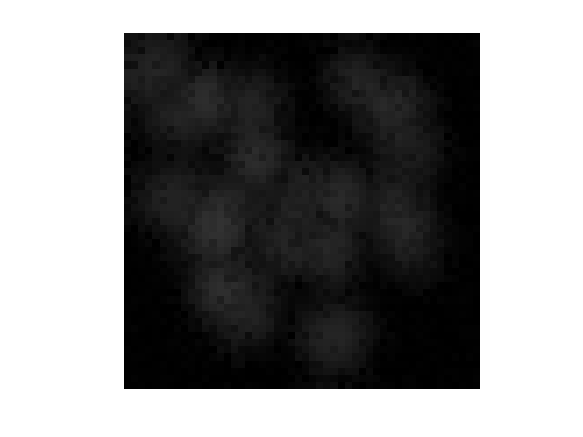

figure; imshow(output.info.summary_image)

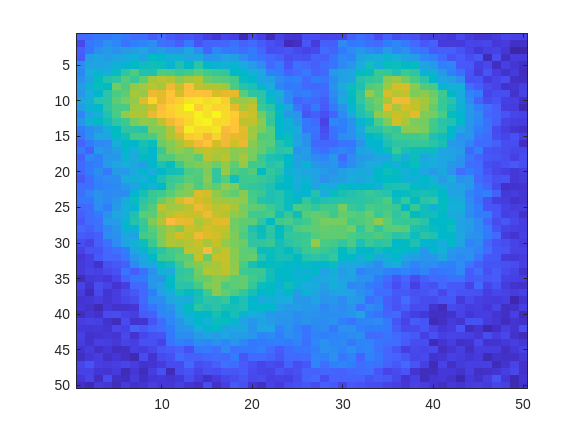

figure; imagesc(output.info.F_per_pixel)

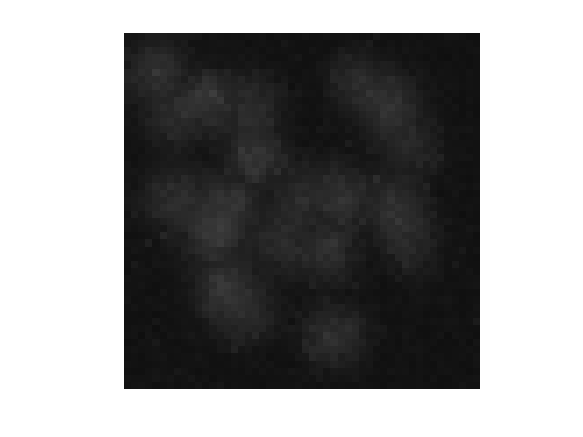

figure; imshow(output.info.max_image)

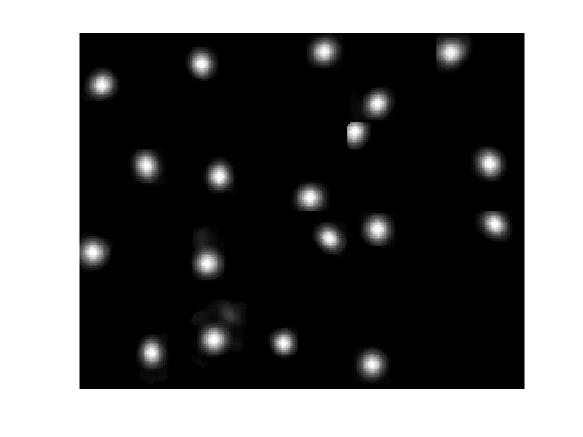

ans =   Image with properties:

           CData: [864×1080 single]
    CDataMapping: 'scaled'

  Show all properties


montage(output.spatial_weights)'

Pick a cell number from the 19 EXTRACTed cells and display its spatial weights. Note that as per the ground truth, there are 20 cells. 

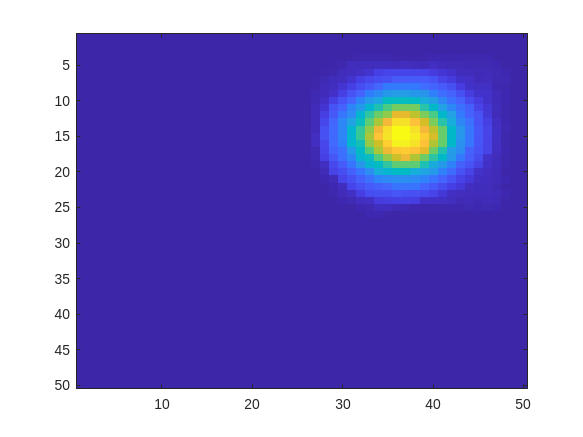

pick=19; 
figure;
imagesc(output.spatial_weights(:,:,pick)')

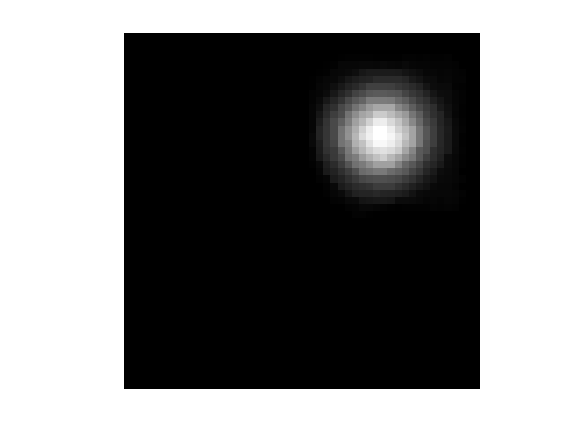

figure;
imshow(output.spatial_weights(:,:,pick)')


[h,w,k]=size(full(output.spatial_weights));
S_ex=reshape(full(output.spatial_weights),h*w,k);
idx_match = match_sets(S_ex, S_ground); %this is a very useful helper function, use this as you need!

T_ex = output.temporal_weights';

## Perform multivariate linear regression for comparison

M_res=reshape(M,2500,2000);
X=mean(M_res,2);
M_res=(M_res-X)./X; %perform dfof
S=S_ex;
T_est=(S'*S)^(-1)*S'*M_res;
% Since this movie does not contain unfound cells or neuropils, this will
% be close to ground truth and EXTRACT outputs!

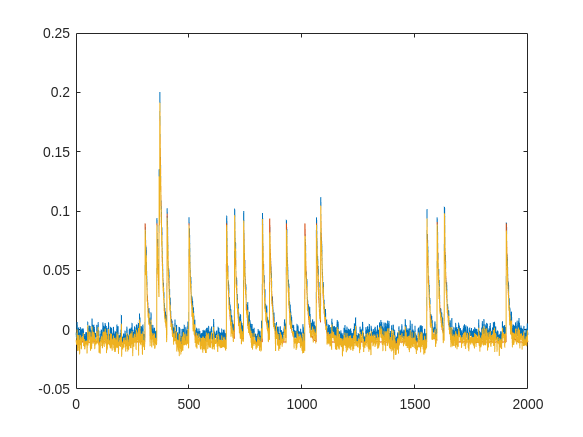


plot(T_ex(idx_match(1,pick),:));
hold on
plot(T_ground(idx_match(2,pick),:))
hold on
plot(T_est(idx_match(1,pick),:))

## Cell checker

### **Internal cell checker with semi-supervised assistance**

EXTRACT has an internally built-in cell-check algorithm,  which employs semi-supervised machine learning methods to aid the user  with the cell checking process. The corresponding file is `cell_check.m`, which takes in two inputs: `M` and `output`. `M` is the movie, whereas `output` is the output generated by EXTRACT that contains cell maps and temporal traces. It has the following properties:

- The user can observe the cell maps during spiking times or click on  the temporal trace map to watch the raw movie during that time window.

- The user can decide whether a candidate is indeed a cell or not.

- The algorithm performs some computations in the background to assist the user, where the user can decide on some acceptance and rejection  thresholds.

- Once a small portion of cell candidates are checked, the algorithm  provides a guess for all the cell candidates. Thus, one does not need to check all the cells.

The figure below explains the process in 4 steps. In this  example, the user had checked only 5 cell candidates and EXTRACT  identified 18 cells and 6 non-cells. We note that this feature is still  experimental and we are constantly working to improve it. We are also  providing an external cell checker in case cell_check fails, which  usually happens when the number of EXTRACT partitions is larger than 1.

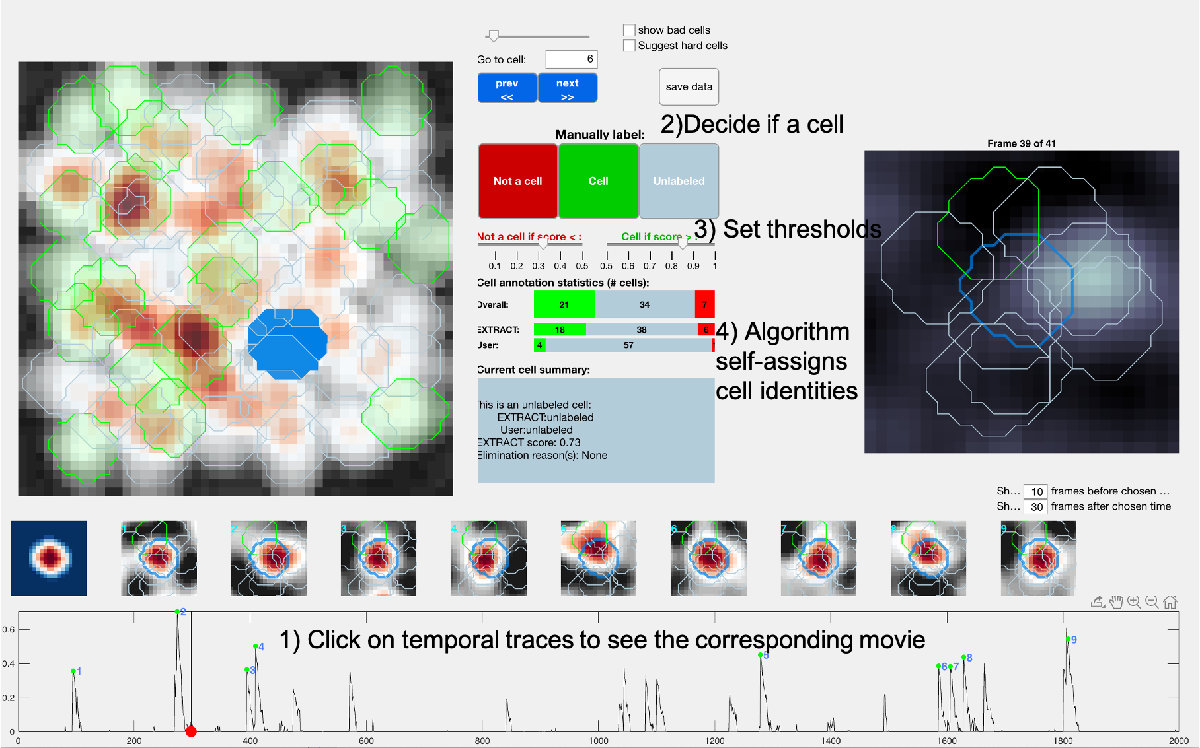

### **External cell checker**

There is also an external cell checker, which is part of the [CIAtah](https://github.com/bahanonu/calciumImagingAnalysis) pipeline. After downloading and including the pipeline in the MATLAB  path, one can use the following code to run the EXTRACT output on the  cell checker of CIAtah pipeline:

options = struct with fields:
                         inputMovie: [50×50×2000 single]
                 inputSignalsSecond: []
                          signalSnr: []
                      inputMovieRaw: []
                              coord: [1×1 struct]
                              valid: 'neutralStart'
               peakTrigMovieMontage: 1
                       nMovieFrames: 10
                     inputMovieDims: []
                   inputDatasetName: '/1'
                            hdf5Fid: []
                       keepFileOpen: 0
                          frameList: []
             nFrameSampleInputMovie: 10
           fractionSampleInputMovie: 0.0100
                    readMovieChunks: 0
                           movieMax: NaN
                           movieMin: NaN
                        movieMinLim: -0.0200
                          movieMean: NaN
           preComputeImageCutMovies: 0
                  nSignalsLoadAsync: 20
                   maxSignalsToShow: 15
 

inputImages size: 50  50  19
inputSignals size: 19  2000
Number of signals or cells in input images (19) and activity traces (19) DO match. Continuing...


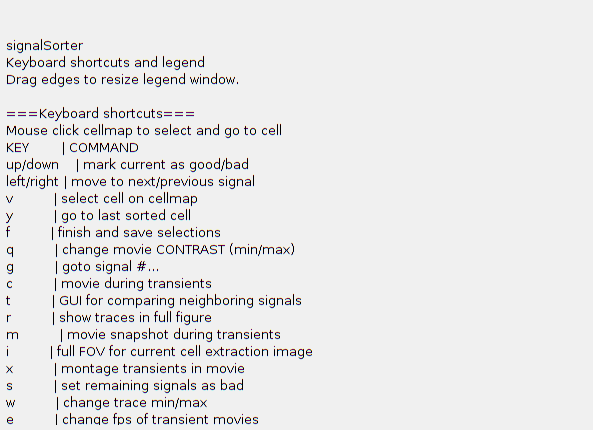

@@@@@@@
Undefined function 'suptitle' for input arguments of type 'char'.

Error in ciapkg.classification.signalSorter>subfxnCreateLegend (line 2362)
	suptitle('signalSorter shortcuts/legend')

Error in ciapkg.classification.signalSorter (line 313)
			instructionStr 

calculating movie max...
calculating movie min...
calculating movie mean...


converting signalMatrix to double
calculating signal peaks...
Opening new parallel worker pool...
=== manageParallelWorkers ===
# Physical Cores: 4
# Logical Cores: 8
User set cores: 
Max cores: 
# workers to open: 7
Starting parallel pool (parpool) using the 'local' profile ...
Connected to the parallel pool (number of workers: 7).
===
SNR type: mean(signal)/std(noise)
cellmap type: max
thresholding images...
***Running normalization: zeroToOne
normalizing movie between 0 and 1
thresholding images...
finding centroids...
Computing image features...
Adding regionprops features to output...
Computing alternative image features...


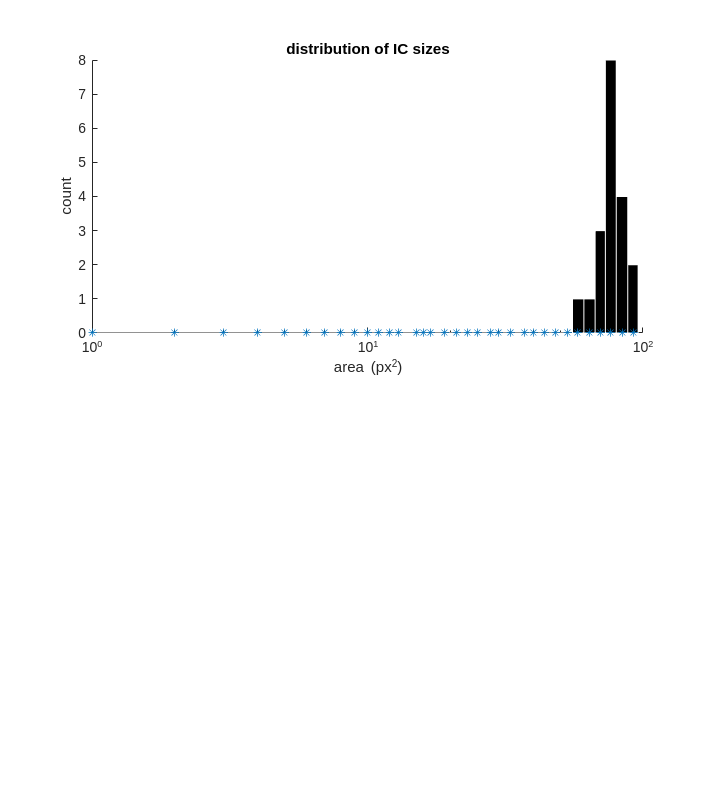

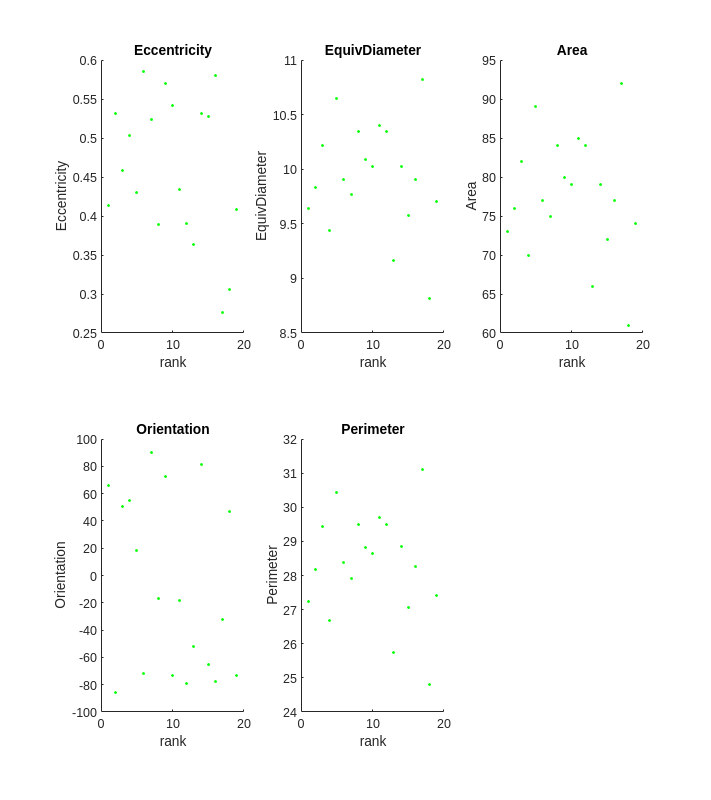

converting signalMatrix to double
calculating signal peaks...
Median filtering before peak statistics
Getting peak statistics: 
finding centroids...
Starting movie images...
Creating crop images: Getting movie images: 

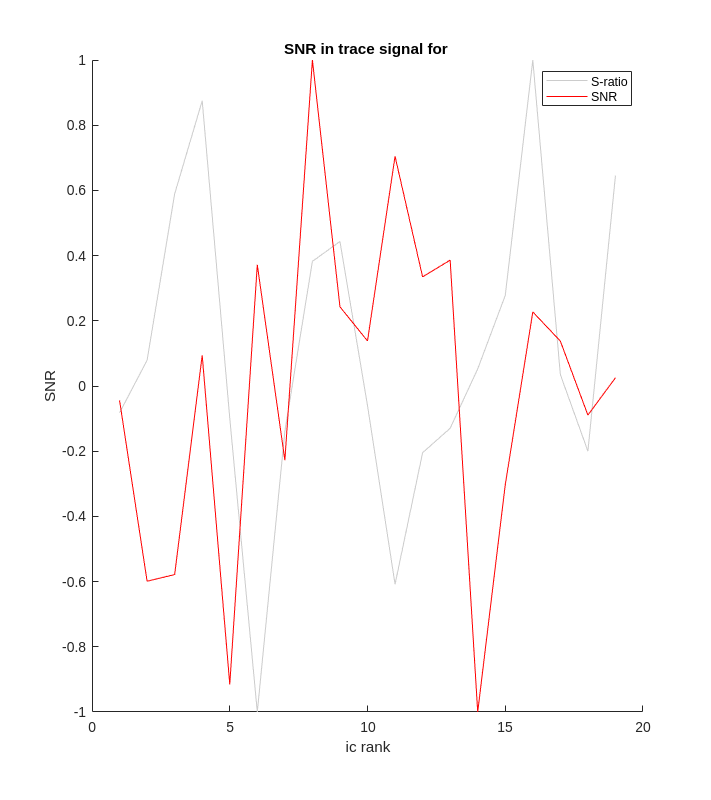

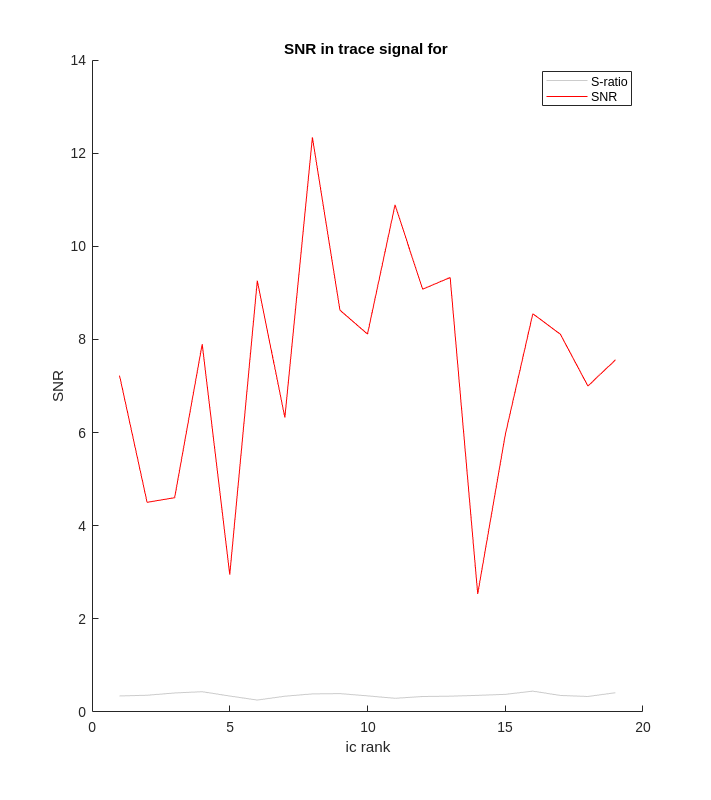

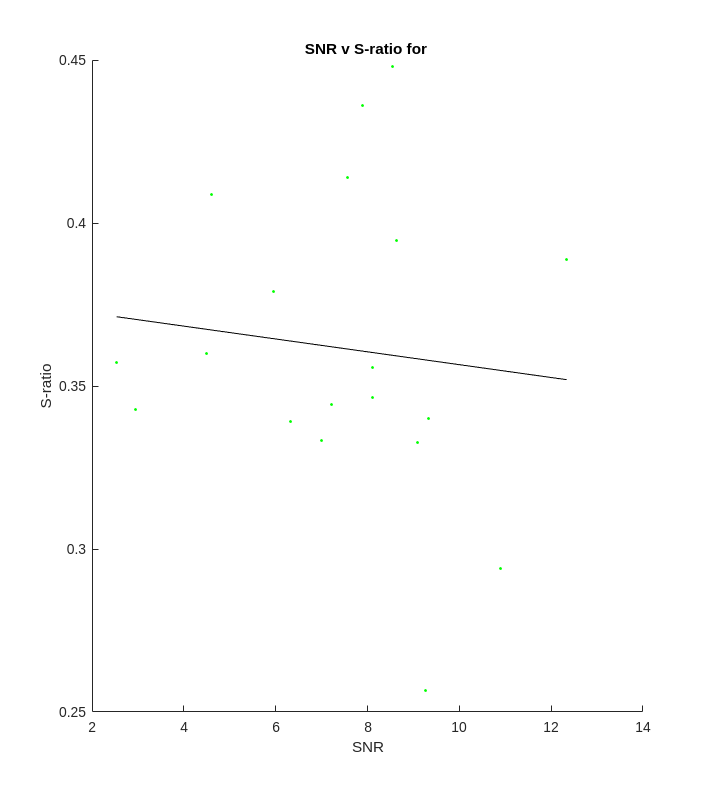

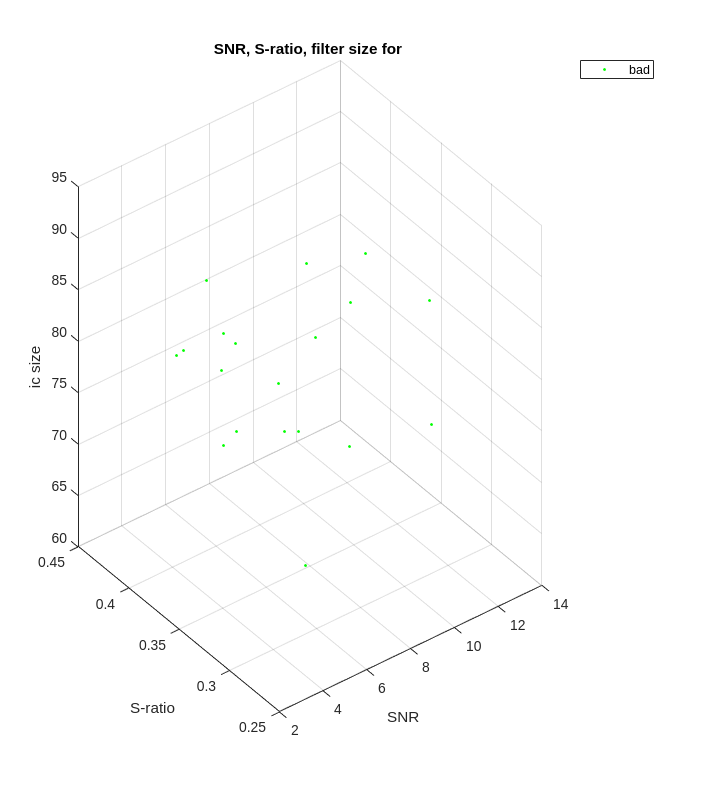

# signals: 19
@@@@@@@
Unrecognized function or variable 'instructionStr'.

Error in ciapkg.classification.signalSorter (line 606)
			[choices, safeExit] = chooseSignals(options,1:nSignals, inputImages,inputSignals,objMap, valid, inputStr,tmpDir,sessionID,signalPeakIdx,signalSnr,inputImagesThres,inputImageSizes,peakOutputStat,ROItraces,imgStats,inputSignalSignal,inputSignalNoise,inputImagesBoundaryIndices,signalPeakIdxOriginal,signalPeaksOriginal,instructionStr);

Error in 

% EXTRACT output is stored in a structure called "output"

% Some configurations for the external cell checker
iopts.inputMovie = M; % movie associated with traces
iopts.valid = 'neutralStart'; % all choices start out gray or neutral to not bias user
iopts.cropSizeLength = 20; % region, in px, around a signal source for transient cut movies (subplot 2)
iopts.cropSize = 20; % see above
iopts.medianFilterTrace = 0; % whether to subtract a rolling median from trace
iopts.subtractMean = 0; % whether to subtract the trace mean
iopts.backgroundGood = [208,229,180]/255;
iopts.backgroundBad = [244,166,166]/255;
iopts.backgroundNeutral = repmat(230,[1 3])/255;

% Run the external cell checker
[inputImagesSorted, inputSignalsSorted, choices] = ciapkg.api.signalSorter(output.spatial_weights, output.temporal_weights', 'options',iopts);

## Understanding hyperparameters

This tutorial is about getting to know the hyperparameters of EXTRACT. For the purpose of this tutorial, download the movie, whose link is given below. This is among those movies that we used for the  Fig. 4 of our paper that introduces EXTRACT. Use the script  'tutorial_fig4.m' as a starting point to tune hyperparameters for most  satisfactory cell extraction process. Read below for the meaning behind  each relevant hyperparameter and the simple ways to optimize them  without diving too deep.

The movie: [https://drive.google.com/file/d/1FGkpTDXgspXddR1GDpgm1ludbIQHFwlS/view?usp=sharing](https://drive.google.com/file/d/1FGkpTDXgspXddR1GDpgm1ludbIQHFwlS/view?usp=sharing)

## Understanding the main modules before diving into hyperparameters

The first step is to understand the general categories  that hyperparameters fall into and that an outside user needs to be able to navigate. While there are quite a few hyperparameters, most of them  are self explanatory (like skip_dff that skips taking delta f over f of  the movie). On the other hand, the best way to understand the parameters is to divide them into corresponding modules. EXTRACT has 3 main  modules:

- **Preprocessing:** At the minimum, the movie  is preprocessed such that the baseline activity of cells correspond to  zero, as is consistent with the assumptions of cell extrraction. There  are other (optional) procedures happening inside the preprocess module  as well, whose aim is to increase the SNR of the movie. We will discuss  these below.

- **Cell finding:** Once the movie is  preprocessed and is ready for cell extraction, EXTRACT first identifies  the regions of interest in a one-by-one fashion. This step is called  cell finding. EXTRACT employs an additional smoothing procedure inside  the cell finding module to increase the efficiency of cell finding but  these procedures do not carry out to cell refinement to prevent  cross-contamination in the final traces. Hyperparameters that belong to  this module usually have 'cellfind' in front of them, meaning that they  ONLY affect the cell finding process.

- **Cell refinement:** Once all the cells are  found in the cell finding module, EXTRACT performs what we call as the  "cell-refinement." The main purpose is to delete the spurious and/or  duplicate cells while accurately estimating the traces by taking into  account all the cells found. Inside the cell refinement module, EXTRACT  computes some quality parameters and discards cell candidates that fail  to score sufficiently on those parameters. The thresholds on these  quality metrics are determined by the outside user via the 'thresholds.' Thus, the most important hyperparameters associated with the cell  refinement module are inside 'config.thresholds.' Keeping the thresholds too tight will lead to some actual cells being discarded, but keeping  them too lose will return too much false-positives and inaccurate trace  estimation.

While there are no particular hyperparameters associated  with them, EXTRACT has two more modules. We will discuss them on another tutorial. For now, it is important to emphasize that running EXTRACT is first understanding these three modules. Other two are optional and can be skipped, although we strongly advise against skipping them!

Finally, almost all the hyperparameters of EXTRACT  controlled by an outside user is defaulted inside the function  'get_defaults.m', which is the only script in the homepage of the  repository. One can and should always double check the exact spelling of the hyperparameters by checking this script. We advise that users do  not change this script, the defaults are picked to be most approprioate  for a general set of movies. This script will never overwrite user given configurations.

## General control hyperparameters

There are a total of 14 general control parameters that  are of interest to us. Among those, only one of them requires an outside input, without which EXTRACT will not run. The rest has defaults, but  we strongly advise to change them as necessary. Here is the list of  parameters and what they do:

- `avg_cell_radius`: The average radius (in  pixels) of a typical cell in the movie. One should not take this  parameter too literally. While cell extraction will generally work fine  within $\pm$3 pixel differences, an order of difference can lead to  issues with cell finding. For a typical movie, this is between 5 and 8.  This parameter has no default. The user needs to input this parameter  from the outside, otherwise the code will not run. `No default`

- `trace_output_option`: EXTRACT has two options  for trace output: 'raw' and 'nonneg'. 'nonneg' outputs only the signal  portion of the trace, consistent with the fundamental assumptions of  EXTRACT. 'raw' outputs signal + noise. `Default: 'nonneg'.`

**Important Note:** We strongly advise to use 'nonneg' over 'raw'. The traces obtained with the former are not  equivalent to the thresholded (over baseline) traces found via the  latter. The former is obtained internally via a different, more accurate solver that iteratively ensures a non-negativity condition at each  step, which prevents structured negative noise to affect subsequent data analysis. This condition is missing from the 'raw' option, thus the  trace estimation is less accurate and may include structured negative  noise that is effectively no different than crosstalk between neighbors. This is why we are not outputting both options at once, as we do not  advise to use the 'raw' option for a general pipeline, only for rare  occasions. Remember, the robustness of EXTRACT is only in the positive  direction, where the signal is.

- `use_gpu` and `parallel_cpu`: If you have a gpu, set the former to one and latter to 0. If not, if you have  multiple cores, set the former to 0 and latter to 1. If you do not have  both, both should be zero. `Defaults: 'true'/'false'`

- `dendrite_aware`: If the movie includes dendrites and/or other non-conventional regions of interest, set this to 1. `Default: false`

- `adaptive_kappa`: Setting this to 1 will  increase the runtime of the movie, but the cell finding module will use  an adaptive approach to estimating the underlying noise distribution  instead of assuming a fixed form. While the default is 0, we find that  this makes a difference in finding cells accurately, especially for low  SNR movies. So, we suggest turning this on whenever possible, or at  least experimenting with it depending on the movie. `Default: false`

- `use_sparse_arrays`: If this is set to 1, the  cell filters (e.g. output.spatial_weights) will be stored as sparse  matrices, instead of usual matrices. This is particularly necessary for  large FOV movies, say larger than 512x512. Otherwise, it is fine to keep it off. `Default: false`

- `hyperparameter_tuning_flag`: If this is on,  the cell extraction process will stop after cell finding + only a single cell refinement step. We will discuss how to use this below for tuning  the thresholds of the cell-refinement process. `Default: false`

- `num_partitions_x` and `num_partitions_y`: Based on these, the movie is partitioned in space and run accordingly  to prevent RAM memory issues. These are not defined inside the  get_defaults.m because EXTRACT performs automatic partitioning based on  size if these are not defined. We suggest always defining these outside  of the algorithm. `No default`

- `remove_duplicate_cells`: If the movie is  partitioned, it is possible that the same cells are found in two  separate slightly overlapping (on the edge only!) partitions. Keep this  on to remove the duplicates after the cell extraction, no reason to turn this off unless extremely special occasions. `Default: true`

- `max_iter`: This defines how many iterations  will take place during the cell-refinement process. At each iteration,  spurious and duplicate cells will be discarded while the cell filters  and traces will be more accurately estimated. Note that each iteration  will increase the accuracy of the cell extraction, but they are also  very costly. Moreover, overfitting might occur after a while, just like  in any other estimation tool. We suggest to keep this parameter no more  than 10. With a good initialization of all the cell filters, this can be taken as small as 0, skipping the cell-refinement procedure all  together. (foreshadowing the final robust regression module!) `Default: 6`

- `T_init` and `S_init`: These  configurations are used to skip the cell finding module and instead  initialize with an outside set of filters and corresponding traces. We  will provide more information on these on a future tutorial. For now, we emphasize that T_init is a 2D n_cell x n_time size matrix, whereas  S_init is also a (flattened in space) 2D n_space x n_cell matrix. `No defaults`

**For a typical run:** Set the average cell radius, define the space partitions and run the algorithm.

## Preprocessing module hyperparameters

The preprocessing module consists of 7 separate processes, 3 of them are on by default. Each process is controlled by a  hyperparameter and the full module is controlled by a single parameter.  Here are the hyperparameters associated with this module, in order of  the processes happening inside the preprocessing module:

- `preprocess`: Turns the preprocessing module on/off. If you turn this off, make sure that the input movie is in the delta F/F form. `Default: True`

- `fix_zero_FOV_strips`: As the name suggests,  this procedure fixes zero strips inside the field of view that are  stemming from motion correction algorithm. `Default: False`

- `medfilt_outlier_pixels`: If the movie has  pixels that are dead or unconventionally on for some technical issue,  this process finds those pixels and replaces them with median filtering. `Default: False`

- `skip_dff`: EXTRACT subtracts the baseline of  the movie and stores the baseline values in a separate file for  normalizing the traces later. We note that EXTRACT performs the division by the baseline AFTER the cell extraction, so this process only  subtracts the baseline, not divides by it. This helps preventing  numerical issues arising from dividing with very small values, sometimes 0. If this parameter is on, EXTRACT skips the subtraction, assuming  that the input movie is already in a delta F/F form. `Default: False`

- `baseline_quantile`: This defines the baseline  value of the movie. Currently, 40% (from below) quantile will be used to estimate the baseline, set it to 0.5 for using median as the baseline.  `Default: 0.4`

- `skip_highpass` : EXTRACT performs a highpass  filtering during the preprocessing step. This is particularly useful for removing large contaminants in the movie. We find that highpass  filtering makes a big difference especially for 1p movies, where it  stabilizes the wandering baseline of cells. This parameter turns off the highpass filtering. `Default: False`

- `spatial_highpass_cutoff`: This parameter  defines how strong the highpass filtering is. A larger value leads to  mild filtering, with no filtering at the infinity. The first change to  the highpass filtering should always be to turn it on or off, usually it is immediately clear if it helps or hurts. Afterwards, this parameter  can be tuned to satisfactory filtering. `Default: 5`

- `temporal_denoising`: This is a slow process,  so it is off by default. This module denoises the movie in time using  wavelets, most movies do not need this. `Default: False`

- `remove_background`: This process removes the  wandering signal baseline and makes sure that cells have a stable  baseline over time. This parameter turns on or off the backround removal process. `Default: True`

## Cell finding module hyperparameters

Cell finding module extracts cell filters from the movie  using a greedy algorithm, in a one-by-one manner. Once a cell is  extracted, it is subtracted from the movie and the full process begins  again. This process ends either once the algorithm reaches a number of  cells pre-defined by the user or if the latest few cells found are  garbage and thus discarded. The following are the parameters associated  with the cell finding module:

- `cellfind_filter_type`: Type of the spatial smoothing filter used for cell finding. Options: `'butter'` (IIR butterworth filter), `'gauss'` (FIR filter with a gaussian kernel), `'wiener'` (wiener filter), `'movavg'` (moving average in space), `'none'` (no filtering). `Default: 'butter'`

- `spatial_lowpass_cutoff`: This is only relevant if the cellfind_filter_type is selected to be butter. Then, this  defines the lowpass cutoff of the filter. A larger value means less  filtering. `Default: 2`

- `moving_radius`: This is only relevant if the  cellfind_filter_type is selected to be butter. This defines the width of the moving average computed in space. `Default: 3`

- `cellfind_min_snr`: Minimum peak SNR (defined  as peak value/noise std) value for an object to be considered as a cell. Increase this if you want to decrease the ratio of false-positives at  the expense of losing some low SNR cells in the process. `Default: 1`

- `thresholds.T_min_snr`: While this is a  threshold parameter, and thus affects the cell refinement process, this  is among the threshold parameters that also affect the cell finding  module. Cells with lower SNR value than `T_min_snr` will be  eliminated immediately, without making it into the cell refinement  module. Lower cellfind_min_snr first before consider lowering this, as  cellfind_min_snr affects only cell finding while this affects two  modules. `Default: 10`

- `thresholds.size_lower_limit` and `thresholds.size_upper_limit`: These factors are multiplied with the average cell area (determined  from the average cell radius) and any cell with an area outside of these will be eliminated before making into the cell refinement module. `Defaults: 0.1 / 10`

- `cellfind_max_steps`: This defines the maximum  number of cells that will be searched inside the FOV per partition.  Picking this too high can lead to memory and time inefficiency issues,  setting it too low would lead to missed cells. We suggest to keep it 1.5 or 2x the expected number of cells (or 1000, whichever is larger) in  the movie, as most garbage found during the cell-finding will be  discarded later in the cell refinement. `Defaults: 1000`

- `cellfind_kappa_std_ratio`: Kappa will be set  to this times the noise std for the component-wise EXTRACT during  initialization. Large kappa means low contamination by non-Gaussian  noise, setting kappa = inf recovers least squares. Note that this  parameter affects only cell finding module, there is a separate kappa  for the cell refinement. Moreover, turning adaptive_kappa on will  overwrite the effects of this parameter, as kappa will be determined  from the movie. `Default: 1`

- `init_with_gaussian`: If true, then during cell finding, each cell is initialized with a gaussian shape prior to robust estimation. If false, then initialization is done with a correlation  image. If cells are of different shape and size, keep this off. `Default: false`.

## Cell refinement module hyperparameters

The parameters associated with the cell refinement module  are the thresholds, which are important for keeping the precision values high. In other words, by tuning them properly, one can decrease the  amount of false-positives that EXTRACT outputs. Additionally, there is  an exclusive kappa parameter for the cell refinement process. Here are  the relevant parameters:

- `kappa_std_ratio`: Kappa will be set to this  times the noise std for the component-wise EXTRACT during  initialization. Large kappa means low contamination by non-Gaussian  noise, setting kappa = inf recovers least squares. Note that this  parameter affects only cell refinement module and turning on the  adaptive_kappa parameter does not affect this. `Default: 1`

- `thresholds.T_min_snr`: Cells with lower peak SNR value than `T_min_snr` will be eliminated during cell refinement. `Default: 10`

- `thresholds.size_lower_limit` and `thresholds.size_upper_limit`: These factors are multiplied with the average cell area (determined  from the average cell radius) and any cell with an area outside of these will be eliminated during cell refinement. `Defaults: 0.1 / 10`

- `thresholds.temporal_corrupt_thresh` and `thresholds.spatial_corrupt_thresh`: Spatial & temporal corruption indices are calculated at each step  of the alternating minimization routine. Images / traces that have an  index higher than these are eliminated. Consider increasing the defaults if actual cells are being discarded during cell refinement. `Defaults: 0.7 / 0.7`

- `thresholds.eccent_thresh:` Cells with  eccentricity higher than this will be eliminated. One can intuitively  think of high eccentricity as cells becoming more elliptic. This  parameter gets rid of blod vessels in most movies, consider lowering the default (say to 3) if this is not the case. `Default: 6`

- `thresholds.low_ST_index_thresh:` and `thresholds.low_ST_corr_thresh:` EXTRACT requires the traces to explain a portion of the fluorescence  signal inside the cell filters. These parameters threshold the ROIs,  where the inferred traces do not explain the activity inside the filter  well. In practice, these parameters are very helpful for removing  garbage cells, but sometimes they can end up removing low SNR cells. `Defaults: 0.01 / 0`

clear;
M = single(hdf5read('Fig4_example.h5','/data'));

config=[];
config = get_defaults(config); %calls the defaults


% Essentials, without these EXTRACT will give an error:
config.avg_cell_radius=6; 

% The movie is large, change the partitions if needed.
config.num_partitions_x=5;
config.num_partitions_y=5; 

% All the rest is to be optimized, which is the purpose of this tutorial!

output=extractor(M,config);

17-Dec-2021 15:21:28: Getting GPU information... 
	 	 	 GPU Device 1 - GeForce GTX 1050 Ti: Available Memory: 3.6 Gb
	 	 	 - Selecting GPU device 1 
17-Dec-2021 15:21:34: Signal extraction on partition 25 (of 25):
	 	 	 Discarding a [0 px top, 0 px bottom, 0 px left, 0 px right] inactive movie region. 
	 	 	 Estimating the average time constant...
	 	 	 Preprocessing movie...
	 	 	 Finding cells with component-wise EXTRACT...
	 	 	 	 noise std: 0.1849 
	 	 	 	 minimum magnitude: 0.2215 
	 	 	 11 cells found after a total of 24 steps. 
	 	 	 Updating S and T with alternating estimation...
	 	 	 End of iter # 1: # cells: 8 (3 removed) 
	 	 	 End of iter # 2: # cells: 8 (0 removed) 
	 	 	 End of iter # 3: # cells: 8 (0 removed) 
	 	 	 End of iter # 4: # cells: 8 (0 removed) 
	 	 	 End of iter # 5: # cells: 8 (0 removed) 
	 	 	 End of iter # 6: # cells: 8 (0 removed) 
	 	 	 Providing non-negative traces. 
	 	 	 Count: 8 cells.
17-Dec-2021 15:21:53: Signal extraction on partition 24 (of 25)

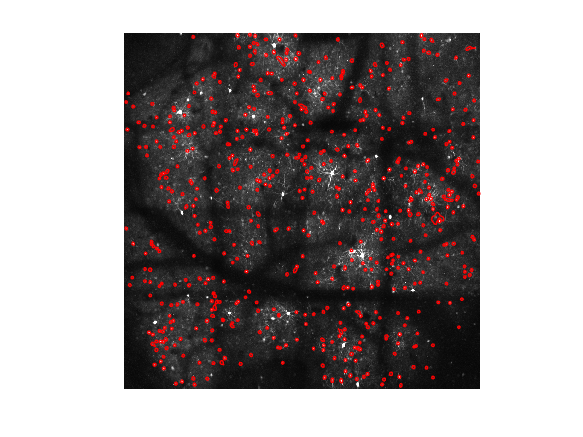


%% Check quality
figure, imshow(max(M,[],3),[0 50]);
plot_cells_overlay(output.spatial_weights,[1,0,0],[])

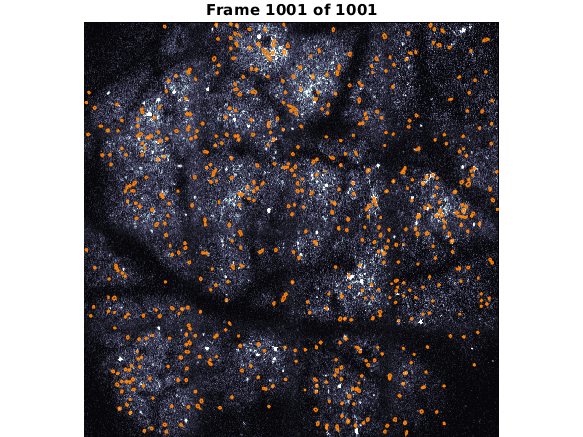

view_movie(M, 'ims',output.spatial_weights,'im_colors',[1, 0.5, 0])
% Check movie

## EXTRACTing cells from a large file with memory constraints

clear
% OPTION 1: Uncomment the following if you want to load the entire 3D movie matrix (~11 GB). Not recommeded for systems with limited memory. 
% M = single(hdf5read('jones.hdf5','/Data/Images'));

% OPTION 2: Instead, pass the movie name as a string. Default option, comment the following if using OPTION 1.
M = 'jones.hdf5:/Data/Images';

% Define the configuration to be used
config=[];
config = get_defaults(config);
config.avg_cell_radius=7;

% If you do not have a native NVIDIA GPU, MATLAB may throw an error. 
if gpuDeviceCount("available")==0 || gpuDevice().DeviceSupported==0
   config.use_gpu=0;
end

% Decide the number of partitions based on available RAM and GPU memory. Typically, for a system with <=24 GB RAM, upto 10 x and y partitions would work. 
config.num_partitions_x=8;
config.num_partitions_y=8;


% Play with internal threshold parameters
config.thresholds.T_min_snr=4;
config.thresholds.spatial_corrupt_thresh=1.5;
config.cellfind_min_snr=0;


output=extractor(M,config);

17-Dec-2021 15:35:59: Getting GPU information... 
	 	 	 GPU Device 1 - GeForce GTX 1050 Ti: Available Memory: 3.4 Gb
	 	 	 - Selecting GPU device 1 
17-Dec-2021 15:36:00: Signal extraction on partition 64 (of 64):
	 	 	 Discarding a [0 px top, 0 px bottom, 0 px left, 0 px right] inactive movie region. 
	 	 	 Estimating the average time constant...
	 	 	 Preprocessing movie...
	 	 	 Finding cells with component-wise EXTRACT...
	 	 	 	 noise std: 0.1635 
	 	 	 	 minimum magnitude: 0.0324 
	 	 	 2 cells found after a total of 21 steps. 
	 	 	 Updating S and T with alternating estimation...
	 	 	 End of iter # 1: # cells: 0 (2 removed) 
	 	 	 Zero cells, stopping. 
	 	 	 Providing non-negative traces. 
	 	 	 Count: 0 cells.
17-Dec-2021 15:37:25: Signal extraction on partition 63 (of 64):
	 	 	 Discarding a [0 px top, 0 px bottom, 0 px left, 0 px right] inactive movie region. 
	 	 	 Estimating the average time constant...
	 	 	 Preprocessing movie...
	 	 	 Finding cells with component-wise 

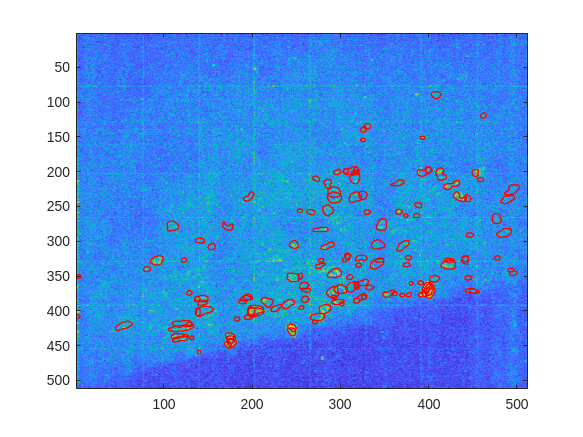

%% Check quality
figure;
%imagesc(output.info.max_image);
imagesc(output.info.summary_image)
plot_cells_overlay(output.spatial_weights,[1,0,0],[])